# **Problem 1.a**

We will examine the performance of $\mathrm{kNN}$ classifier on the Liquid, Iris and Normal datasets. In order to perform a $\mathrm{kNN}$ classification with the leave-one-out method, we will simply classify the sample that we have left out in each step using the $\mathrm{kNN}$ algorithm. I.e., we will take the top $k$ closest data points to this sample using some measure of distance (here we will use Euclidean distance) and then we will determine the class of the point in with respect to a majority voting scheme.

## **Analysis of the Iris Data:**

First we will read in the data set:

clearvars
X_Iris = load("Data/Iris-Data_dat.txt");

Now we will perform $\mathrm{kNN}$ on this data set using the leave-one-out method as described above for $k\in \left\lbrace 1,2,3\right\rbrace$.

num_classes = 3;
input_size = size(X_Iris, 1)

input_size = 150

I: Classification

preds = zeros([input_size, 3]);
X_Iris_labels = X_Iris(:, 1);
X_Iris_feats = X_Iris(:, 2:5);
for i=1:input_size
    % leave one out as test
    X_test_feats = X_Iris_feats(i,:);
    X_test_label = X_Iris_labels(i);
    % the rest will be used to infer the class of the left out sample
    rest_feats = X_Iris_feats([1:i-1, i+1:end],:);
    rest_labels = X_Iris_labels([1:i-1, i+1:end]);
    % align the test_feats with the rest_feats by repeating test_feats,
    % input_size - 1 times
    % then we can calculate the pairwise euclidean distance
    dists = sqrt(sum((repmat(X_test_feats, [input_size - 1, 1]) - rest_feats).^2, 2));
    % sort these distances but keep the original indicies as we will use
    % them to determine the original label that was assigned to a sample
    [~, nearest] = sort(dists);
    % for each k value from 1 to 3
    for k = 1:3
        % number of representatives of each class
        reps = zeros([num_classes, 1]);
        % take the k-nearest neighbors
        for j = 1:k
            % extract actual label using the indicies that we saved from
            % line 21.
            actual_label = rest_labels(nearest(j));
            % add to the number of representatives of this class
            reps(actual_label) = reps(actual_label) + 1;
        end
        % maximum number of representatives from all of the classes is the
        % label assigned to the test sample
        [~, preds(i,k)] = max(reps);
    end
end

II: Evaluation

For $k=1$:

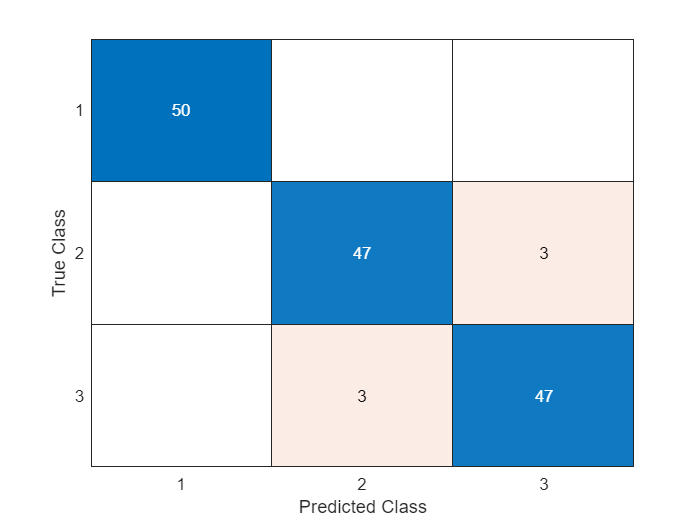

cc1 = confusionchart(X_Iris_labels, preds(:,1));

accuracy1 = length(find(preds(:,1) == X_Iris_labels))/input_size

accuracy1 = 0.9600

For $k=2$:

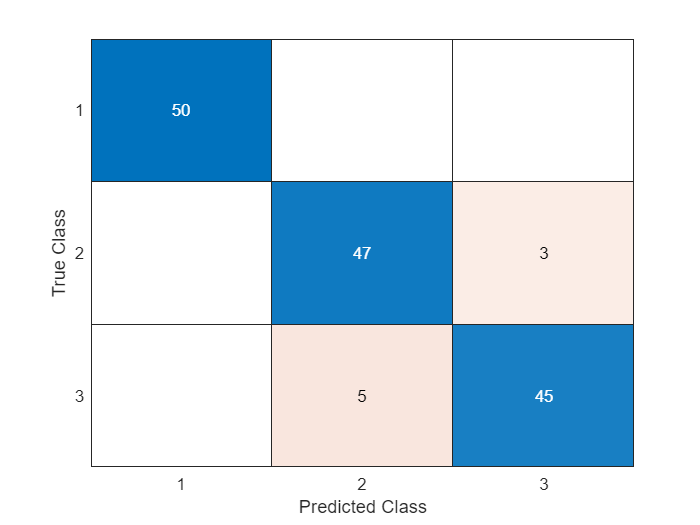

cc2 = confusionchart(X_Iris_labels, preds(:,2));

accuracy2 = length(find(preds(:,2) == X_Iris_labels))/input_size

accuracy2 = 0.9467

For $k=3$:

cc3 = confusionchart(X_Iris_labels, preds(:,3));

accuracy3 = length(find(preds(:,3) == X_Iris_labels))/input_size

accuracy3 = 0.9600

As we can see all of the models seem to performing similarly accurately although we expect that with the increase of $k$ the accuracy will converge to that of an optimal Bayes Classifier. The samples of this dataset do not appear to be intertwined enough to showcase the difference between different choices of $k$.

## **Analysis of the Liquid Data:**

We will perform the exact same analysis on the Liquid dataset. Redundant details have been removed for brevity.

clearvars
X_Liquid = load("Data/Liquid-Data_dat.txt");
num_classes = 3;
input_size = size(X_Liquid, 1)

input_size = 178

I: Classification

preds = zeros([input_size, 3]);
X_Liquid_labels = X_Liquid(:, 1);
X_Liquid_feats = X_Liquid(:, 2:7);
for i=1:input_size
    X_test_feats = X_Liquid_feats(i,:);
    X_test_label = X_Liquid_labels(i);
    rest_feats = X_Liquid_feats([1:i-1, i+1:end],:);
    rest_labels = X_Liquid_labels([1:i-1, i+1:end]);
    dists = sqrt(sum((repmat(X_test_feats, [input_size - 1, 1]) - rest_feats).^2, 2));
    [~, nearest] = sort(dists);
    for k = 1:3
        reps = zeros([num_classes, 1]);
        for j = 1:k
            actual_label = rest_labels(nearest(j));
            reps(actual_label) = reps(actual_label) + 1;
        end
        [~, preds(i,k)] = max(reps);
    end
end

II: Evaluation

For $k=1$:

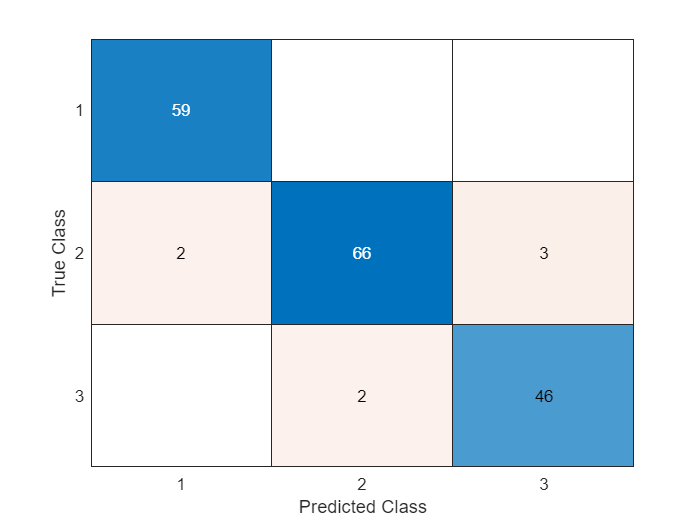

cc1 = confusionchart(X_Liquid_labels, preds(:,1));

accuracy1 = length(find(preds(:,1) == X_Liquid_labels))/input_size

accuracy1 = 0.9607

For $k=2$:

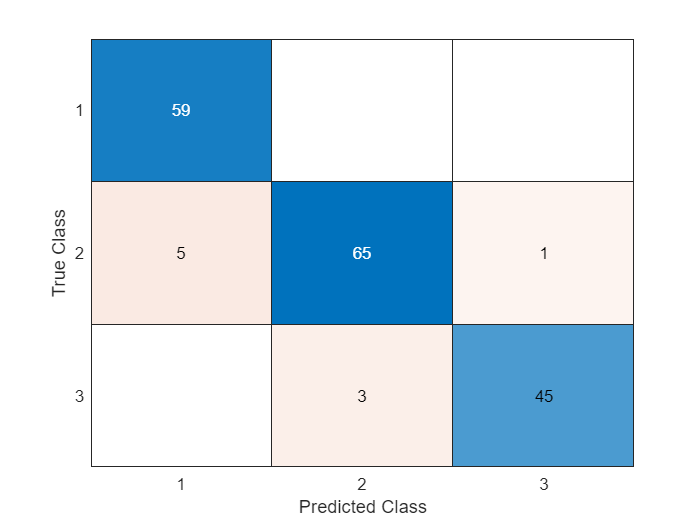

cc2 = confusionchart(X_Liquid_labels, preds(:,2));

accuracy2 = length(find(preds(:,2) == X_Liquid_labels))/input_size

accuracy2 = 0.9494

For $k=3$:

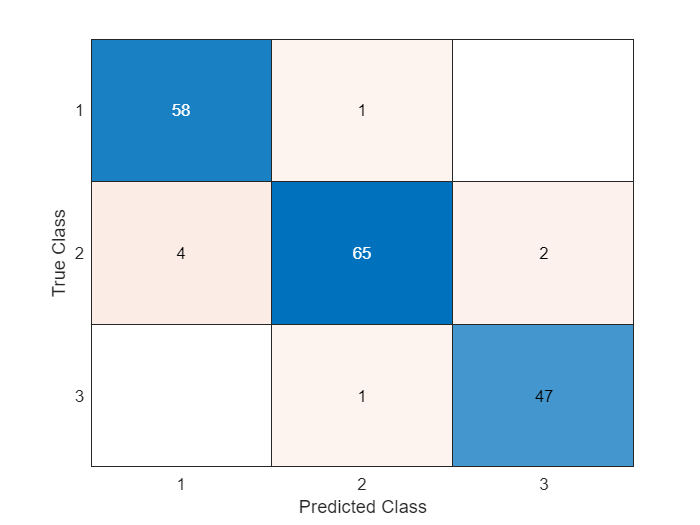

cc3 = confusionchart(X_Liquid_labels, preds(:,3));

accuracy3 = length(find(preds(:,3) == X_Liquid_labels))/input_size

accuracy3 = 0.9551

## **Analysis of the Normal Data:**

We will pour both the test and train data on top of each other and perform the leave-one-out analysis on the Normal data as we did in the prior sections:

clearvars
X_Normal_Test = load("Data/Normal-Data-Testing_dat.txt");
X_Normal_Train = load("Data/Normal-Data-Training_dat.txt");
X_Normal = [X_Normal_Train; X_Normal_Test];
num_classes = 2;
input_size = size(X_Normal, 1)

input_size = 2000

I: Classification

preds = zeros([input_size, 3]);
X_Normal_labels = X_Normal(:, 1);
X_Normal_feats = X_Normal(:, 2:3);
for i=1:input_size
    X_test_feats = X_Normal_feats(i,:);
    X_test_label = X_Normal_labels(i);
    rest_feats = X_Normal_feats([1:i-1, i+1:end],:);
    rest_labels = X_Normal_labels([1:i-1, i+1:end]);
    dists = sqrt(sum((repmat(X_test_feats, [input_size - 1, 1]) - rest_feats).^2, 2));
    [~, nearest] = sort(dists);
    for k = 1:3
        reps = zeros([num_classes, 1]);
        for j = 1:k
            actual_label = rest_labels(nearest(j));
            reps(actual_label) = reps(actual_label) + 1;
        end
        [~, preds(i,k)] = max(reps);
    end
end

II: Evaluation

For $k=1$:

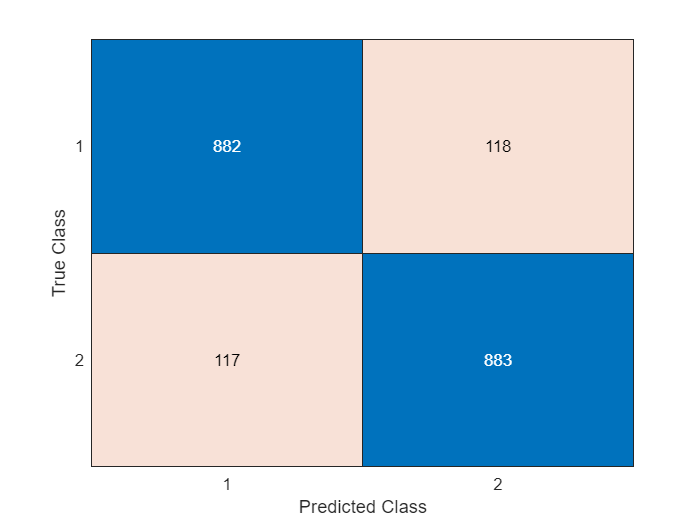

cc1 = confusionchart(X_Normal_labels, preds(:,1));

accuracy1 = length(find(preds(:,1) == X_Normal_labels))/input_size

accuracy1 = 0.8825

For $k=2$:

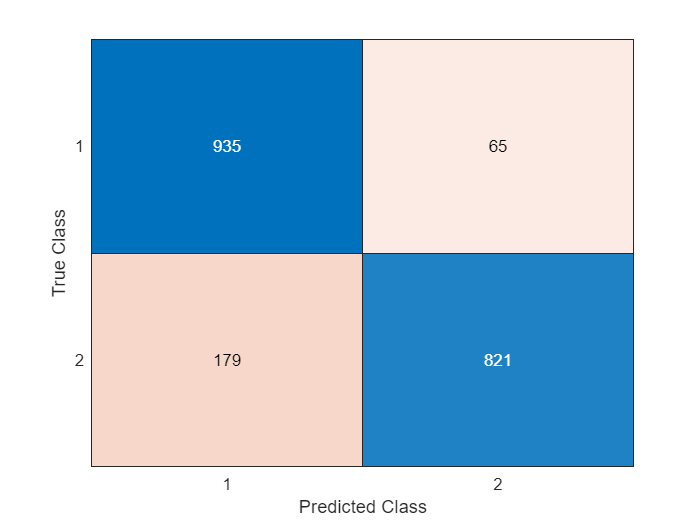

cc2 = confusionchart(X_Normal_labels, preds(:,2));

accuracy2 = length(find(preds(:,2) == X_Normal_labels))/input_size

accuracy2 = 0.8780

For $k=3$:

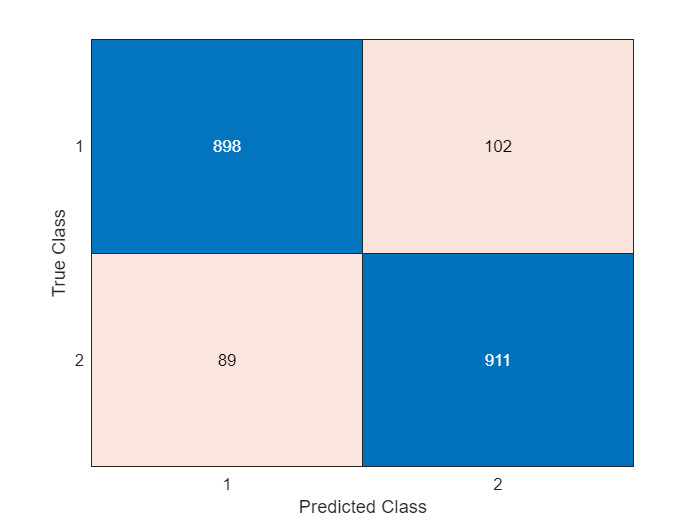

cc3 = confusionchart(X_Normal_labels, preds(:,3));

accuracy3 = length(find(preds(:,3) == X_Normal_labels))/input_size

accuracy3 = 0.9045

All in all, it appears that the with the increase of $k$, accuracy should improve but for small even $k$s (like $2$) where ties are extremely likely near the decision boundary, the $\mathrm{kNN}$ scheme seems to be performing worse. However, for large enough $k$ this should not matter as it is far less likely to happen.